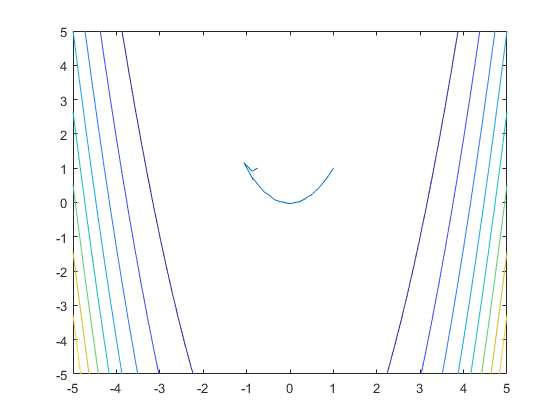

% Copyright: Theocharis Karathymios (github name: karatgit)
% Minimization of function f using the Broyden-Fletcher-Goldfarb-Shanno (BFGS) algorithm with Armijo Line Search
% Define the objective function
syms x y
f(x,y) = 100*(y-x.^2).^2 + (1-x).^2;
% Calculate gradient of f
grad_f(x,y) = gradient(f);
% Set initial point and Armijo constants
x_k = -3/4;
y_k = 1;
x_k_old = x_k;
y_k_old = y_k;
g = 0.5;
s = 0.5;
a = 1;
epsilon = 0.001;
% gradf(xk)
gradf_xk = double(grad_f(x_k,y_k));
gradf_xk_old = double(grad_f(x_k_old,y_k_old));
% Starting point for later storage of x,y
X = x_k;
Y = y_k;
J = log((x_k-1)^2+(y_k-1)^2);
H = eye(2);
%________BFGS Algorithm_______
while norm(gradf_xk)>epsilon
    %dk selection
    dk = -H*gradf_xk;
    %_________Armijo step_________
    f_xk = double(f(x_k,y_k));
    f_adk = double(f(x_k+a*dk(1,1),y_k+a*dk(2,1)));
    a = 1;
    while f_adk - f_xk > g*a*gradf_xk'*dk
    a = a*s;
    f_adk = double(f(x_k+a*dk(1,1),y_k+a*dk(2,1)));
    end
    %_____________________________
    %hold the previous point
    x_k_old = x_k;
    y_k_old = y_k;
    %take step
    x_k = x_k + a*dk(1,1);
    y_k = y_k + a*dk(2,1);
    J_new = log((x_k-1)^2+(y_k-1)^2);
    X = [X x_k];
    Y = [Y y_k];
    J = [J J_new];
    gradf_xk = double(grad_f(x_k,y_k));
    gradf_xk_old = double(grad_f(x_k_old,y_k_old));
    gamma = gradf_xk - gradf_xk_old;
    delta = [x_k-x_k_old; y_k-y_k_old];
    u = sqrt(gamma'*H*gamma)*(delta/(delta'*gamma)-(H*gamma)/(gamma'*H*gamma));
    H = H + (delta*delta')/(delta'*gamma) - (H*(gamma*gamma')*H)/(gamma'*H*gamma) + u*u';
end
optimal_point = [x_k;y_k];
fcontour(f);
hold on;
plot(X,Y);
hold off;

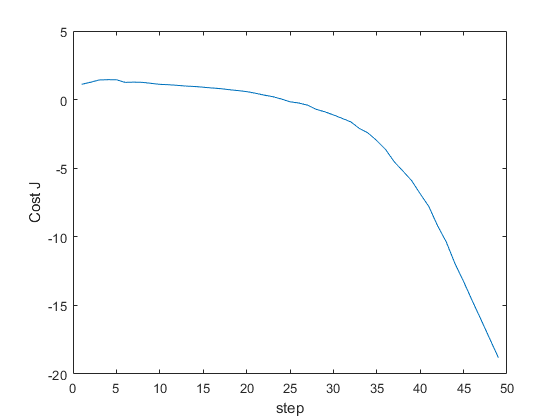

plot(J);
ylabel('Cost J');
xlabel('step');